clear all;
clc;
close all;

XK = [6, -5 + 11i, 0, -5 - 11i];
CXK = conj(XK);

x=CXK;
p = nextpow2(length(x));
x = [x zeros(1, (2^p) - length(x))];
N = length(x);
S = log2(N);
Half = N / 2;
for stage = 1:S
    for index = 0:(N / (2^(stage - 1))):(N - 1)
        for n = 0:(Half - 1)
            pos = n + index + 1;
            pow = (2^(stage - 1)) * n;
            w = exp((-1i) * (2 * pi) * pow / N);
            a = x(pos) + x(pos + Half);
            b = (x(pos) - x(pos + Half)) .* w;
            x(pos) = a;
            x(pos + Half) = b;
        end
    end
    Half = Half / 2;
end
y = bitrevorder(x);

disp("Radix-2 DIF FFT method result")

Radix-2 DIF FFT method result


y = conj(bitrevorder(x)) ./ N

y =   -1.0000 + 0.0000i  -4.0000 + 0.0000i   4.0000 + 0.0000i   7.0000 - 0.0000i



Xvk = ifft(XK);
disp("Direct computation")

Direct computation


Xvk

Xvk =     -1    -4     4     7


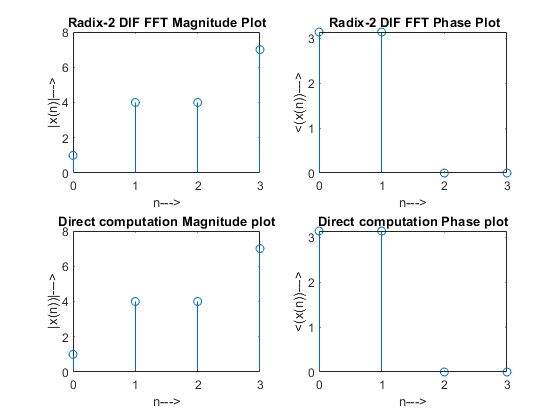


k = 0:N - 1;
subplot(2, 2, 1)
stem(k, abs(y))
xlabel('n--->')
ylabel('|x(n)|--->')
title('Radix-2 DIF FFT Magnitude Plot')

subplot(2, 2, 2)
stem(k, angle(y))
xlabel('n--->')
ylabel('<(x(n))--->')
title(' Radix-2 DIF FFT Phase Plot')

subplot(2, 2, 3)
stem(k, abs(Xvk))
xlabel('n--->')
ylabel('|x(n))|--->')
title('Direct computation Magnitude plot')

subplot(2, 2, 4)
stem(k, angle(Xvk))
xlabel('n--->')
ylabel('<(x(n))--->')
title('Direct computation Phase plot')